# **Week E1 : Digital Pre-Compensation**

This script invesitagtes digital pre-compnesation of CD and phase shifts due to the Kerr effect at the transmitter to simplifiy the DSP at the receiver 

## **Transmitter**

The model of the transmitter consists of the following elements:

- A symbol generator which modulates source bits using 16-QAM

- A pulse shaper which creates an electrical signal using the generated symbols

- An IQ modulator which modulates the output of a laser according to an electrical signal

### Modulation

clearvars

% Parameters
NSymb = 10000; % No. of symbols 
SpS = 2; % Samples per symbol
Rs = 50e9; % Symbol rate in symbols/sec
T = 1/(SpS*Rs); % Sampling period in s
t= [0:1:NSymb*SpS - 1]*T; % Time vector for plotting time-series data

% voltageLevelsQPSK = [asin(-1/sqrt(2)), asin(1/sqrt(2))]'; % Discrete voltages for QAM
% voltageLevelsQAM = [asin(-3/sqrt(10)), asin(-1/sqrt(10)), asin(1/sqrt(10)), asin(3/sqrt(10))]';
% DCOffset = 0; % DC offset of modulated current in V

% --------------------------------------------------------------------------------------

% Generating random bit sequence(s)
sourceBitsQAM = randi([0 1], NSymb*4, 1); % Matrix of source bits for QAM
sourceIntsQAM = bit2int(sourceBitsQAM, 4); % Vector of source bits converted to ints
sourceSymbolsQAM = qammod(sourceIntsQAM, 16, UnitAveragePower=true); % Maps source bit vector to symbol vector

vI_QAM = real(sourceSymbolsQAM);
vQ_QAM = imag(sourceSymbolsQAM);

vI_QAM_upsampled = repelem(vI_QAM, SpS, 1); % Upsampling according to SpS
vQ_QAM_upsampled = repelem(vQ_QAM, SpS, 1); % Upsampling according to SpS

% Visualising in-phase and quadrature voltage
% stairs(t(1:10*SpS), vI_QAM_upsampled(1:10*SpS,1), "o-");
% hold on
% stairs(t(1:10*SpS), vQ_QAM_upsampled(1:10*SpS,1), "o-");
% title("Modulated Voltage for QAM")
% xlabel("Time / s")
% ylabel("Voltage / V")
% legend("In-phase", "Quadrature")
% grid on
% hold off

### Pulse Shaping

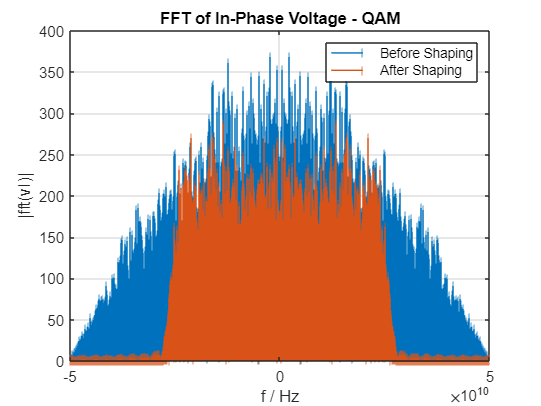

% RRC filter parameters
filterSpan = 16; % Span of RRC filter in no. of symbols
rollOff = 0.1;
filterResponse = rcosdesign(rollOff, filterSpan, SpS, "sqrt")';
samples = 1+(NSymb-1)*SpS + filterSpan*SpS;
v_shaped_t = [0:1:samples-1]*T;

% Visualisation of RRC filter
filterResponse_t = [0:1:filterSpan*SpS]*T; % time vector for the filter response
% filterResponse_t_interp = [0:0.25:filterSpan*SpS]*T;
% filterResponse_interp = interp1(filterResponse_t, filterResponse, filterResponse_t_interp, "spline");
% plot(filterResponse_t, filterResponse, "o", filterResponse_t_interp, filterResponse_interp, ":.");

% stem(filterResponse_t, filterResponse, '-o');
% title('Impulse Response of RRC Filter - upfirdn');
% xlabel('Time / s');
% ylabel('Normalised Amplitude');
% grid on

% stem(filterResponse_t, RRC(filterSpan, SpS, rollOff), '-o');
% title('Impulse Response of RRC Filter - PulseShaping');
% xlabel('Time / s');
% ylabel('Normalised Amplitude');
% grid on

% rcosdesignPw = mean(abs(filterResponse).^2)
% RRCPw = mean(abs(RRC(filterSpan, SpS, rollOff)).^2)

% ---------------------------------------------------------------------------

% Using RRC filter to shape vI and vQ
vI_QAM_shaped = upfirdn(vI_QAM, filterResponse, SpS, 1); vQ_QAM_shaped = upfirdn(vQ_QAM, filterResponse, SpS, 1);

% vI_QAM_shaped = PulseShaping(vI_QAM, SpS, filterSpan, rollOff); 
% vQ_QAM_shaped = PulseShaping(vQ_QAM, SpS, filterSpan, rollOff); 

% Frequency spectrum of voltage waveforms before filtering
fft_vI_QAM = fftshift(fft(vI_QAM_upsampled(:,1))); % FFT of noisy signal before shaping
freqArr = [-NSymb*SpS/2:NSymb*SpS/2 - 1]/(T*NSymb*SpS);

fft_vI_QAM_shaped = fftshift(fft(vI_QAM_shaped(:,1))); % FFT of nosiy signal after shaping
freqArr_shaped = [-samples/2:samples/2 - 1]/(T*samples);

stem(freqArr, abs(fft_vI_QAM), "|");
hold on
stem(freqArr_shaped, abs(fft_vI_QAM_shaped), "|");
title("FFT of In-Phase Voltage - QAM");
xlabel("f / Hz");
ylabel("|fft(vI)|");
legend("Before Shaping", "After Shaping");
hold off
grid on


% Visualising pulse-shaped voltages
% stairs(v_shaped_t(1:10*SpS + filterSpan), vI_QAM_upsampled(1:10*SpS + filterSpan,1), "o-");
% hold on
% plot(v_shaped_t(1:10*SpS + filterSpan), vI_QAM_shaped(1:10*SpS + filterSpan,1), "o-");
% title("Shaped In-Phase Voltage - QAM");
% ylabel("Voltage / V");
% xlabel('Time / s');
% legend("Before shaping", "After shaping");
% grid on
% hold off

bandwidth = 0.5*(1+rollOff)/T

bandwidth = 5.5000e+10

### Pre-Compensation

% Pre-compensation of CD
D = 17; % Group velocity dispersion in ps/nm/km
CLambda = 1550e-9; % Central wavelength of optical carrier in m
linkLength = 50e3; % Fibre link length in m
c = 299792458; % Speed of light in m/s

N_CD = ceil(6.67*(D*1e-6)*(CLambda^2)*linkLength*(Rs^2)*SpS/(2*pi*c)) % CD Equalizer Length#

N_CD = 37

N_CD = 50

N_CD = 50

N_FFT = 2^9;

v_preCD = OverlapSaveCDC(vI_QAM_upsampled+1i*vQ_QAM_upsampled, D, linkLength, CLambda, Rs, 1, SpS, N_FFT, N_CD);
v_preCD_shaped = OverlapSaveCDC(vI_QAM_shaped+1i*vQ_QAM_shaped, D, linkLength, CLambda, Rs, 1, SpS, N_FFT, N_CD);

### IQ Modulation

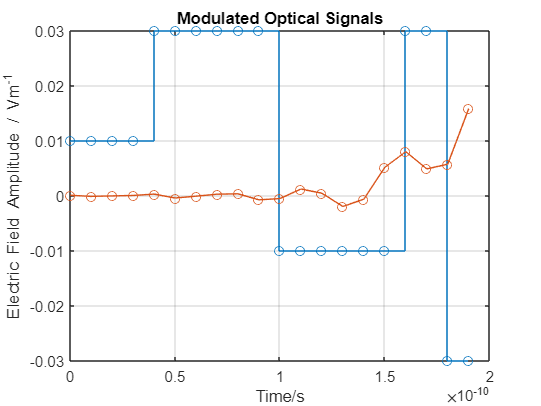

% Initialising laser parameters
lineWidth = 0;
laserPw_dBm = 0;
laserPw_Lin = 1e-3*10^(laserPw_dBm/10);

% Generating output from laser modelled as a continuous-wave source
laserE = Laser(laserPw_dBm, lineWidth, SpS, Rs, NSymb, 1); % Laser output to be used with unshaped signals
laserE_shaped = Laser(laserPw_dBm, lineWidth, SpS, Rs, samples/SpS, 1); % Laser output to be used with shaped signals

% Visualising output from laser
% plot(t(1:20), real(laserE(1:20)), "o-");
% title("Laser Output as a Continous Wave");
% xlabel("Time/s")
% ylabel("Electric Field Amplitude / Vm^{-1}");
% grid on

% Modulating optical signal using IQM
Vpi = pi/2; % Voltge required to change phase of E-field by pi

% Without precompensation
modOpticSigQAM = (vI_QAM_upsampled+1i*vQ_QAM_upsampled).*laserE; % Unshaped signal
modOpticSigQAM_shaped = (vI_QAM_shaped+1i*vQ_QAM_shaped).*laserE_shaped; % Shaped signal

% With precompensation
modOpticSigQAM_preCD = (v_preCD).*laserE; % Unshaped signal
modOpticSigQAM_preCD_shaped = (v_preCD_shaped).*laserE_shaped; % Shaped signal

% Visualising modulated optical signals
stairs(t(1:10*SpS), real(modOpticSigQAM(1:10*SpS,1)), "o-");
hold on
plot(t(1:10*SpS), real(modOpticSigQAM_shaped(1:10*SpS,1)), "o-");
title("Modulated Optical Signals")
xlabel("Time/s")
ylabel("Electric Field Amplitude / Vm^{-1}")
grid on
hold off

## Optical Channel

### Inserting CD

% Adding CD to non-precompensated signal
channelOutQAM = CDInsertion(modOpticSigQAM, SpS, Rs, D, CLambda, linkLength, 1); 
channelOutQAM_shaped = CDInsertion(modOpticSigQAM_shaped, SpS, Rs, D, CLambda, linkLength, 1); 

% Adding CD to precompensated signal
channelOutQAM_preCD = CDInsertion(modOpticSigQAM_preCD, SpS, Rs, D, CLambda, linkLength, 1); 
channelOutQAM_preCD_shaped = CDInsertion(modOpticSigQAM_preCD_shaped, SpS, Rs, D, CLambda, linkLength, 1); 


### Adding AWGN

% Adding AWGN to the modulated optical signals

SNRb_dB = [0:2:10]; % SNR per bit in dB
SNRb_Lin = 10.^(SNRb_dB/10); % linear SNR per symbol

% Initialising signals
channelOutQAM = repelem(channelOutQAM, 1, 1, length(SNRb_dB));
channelOutQAM_shaped = repelem(channelOutQAM_shaped, 1, 1, length(SNRb_dB));

channelOutQAM_preCD = repelem(channelOutQAM_preCD, 1, 1, length(SNRb_dB));
channelOutQAM_preCD_shaped = repelem(channelOutQAM_preCD_shaped, 1, 1, length(SNRb_dB));

% noisePw = zeros(1,length(SNRb_dB)); 
% noisePw_shaped = zeros(1,length(SNRb_dB));

for i=1:length(SNRb_dB)
    % Without precompensation
    channelOutQAM(:,:,i) = awgn(channelOutQAM(:,:,i), convertSNR(SNRb_dB(i),'ebno', samplespersymbol=1, bitspersymbol=4), 'measured'); % Unshaped
    channelOutQAM_shaped(:,:,i) = awgn(channelOutQAM_shaped(:,:,i), convertSNR(SNRb_dB(i),'ebno', samplespersymbol=2, bitspersymbol=4), 'measured'); % Shaped

    % With precompensation
    channelOutQAM_preCD(:,:,i) = awgn(channelOutQAM_preCD(:,:,i), convertSNR(SNRb_dB(i),'ebno', samplespersymbol=1, bitspersymbol=4), 'measured'); % Unshaped
    channelOutQAM_preCD_shaped(:,:,i) = awgn(channelOutQAM_preCD_shaped(:,:,i), convertSNR(SNRb_dB(i),'ebno', samplespersymbol=2, bitspersymbol=4), 'measured'); % Shaped
end

## DSP

### Scaling 

% Scaling factor between output of IQM and output of optical front-end
laserEMag = sqrt(laserPw_Lin);
scaleFactor = laserEMag;

% Cancelling the scaling factor

% Unshaped signals
voltageQAM = channelOutQAM/scaleFactor; voltageQAM_preCD = channelOutQAM_preCD/scaleFactor;

clear voltageQAM_shaped_I voltageQAM_shaped_Q voltageQAM_preCD_shaped_I voltageQAM_preCD_shaped_Q;

% Shaped signals
for i=1:length(SNRb_dB)
    % Without precompensation
    voltageQAM_shaped_I(:,:,i) = upfirdn(real(channelOutQAM_shaped(:,:,i))/scaleFactor, filterResponse, 1, 1); 
    voltageQAM_shaped_Q(:,:,i) = upfirdn(imag(channelOutQAM_shaped(:,:,i))/scaleFactor, filterResponse, 1, 1); 
    
    % With precompensation
    voltageQAM_preCD_shaped_I(:,:,i) = upfirdn(real(channelOutQAM_preCD_shaped(:,:,i))/scaleFactor, filterResponse, 1, SpS); 
    voltageQAM_preCD_shaped_Q(:,:,i) = upfirdn(imag(channelOutQAM_preCD_shaped(:,:,i))/scaleFactor, filterResponse, 1, SpS); 
end

voltageQAM_shaped_I = voltageQAM_shaped_I(filterSpan*SpS+1:end - filterSpan*SpS+1,:,:);
voltageQAM_shaped_Q = voltageQAM_shaped_Q(filterSpan*SpS+1:end - filterSpan*SpS+1,:,:);
voltageQAM_preCD_shaped_I = voltageQAM_preCD_shaped_I(filterSpan+1:end-filterSpan,:,:);
voltageQAM_preCD_shaped_Q = voltageQAM_preCD_shaped_Q(filterSpan+1:end-filterSpan,:,:);

### Overlap and Save CDC

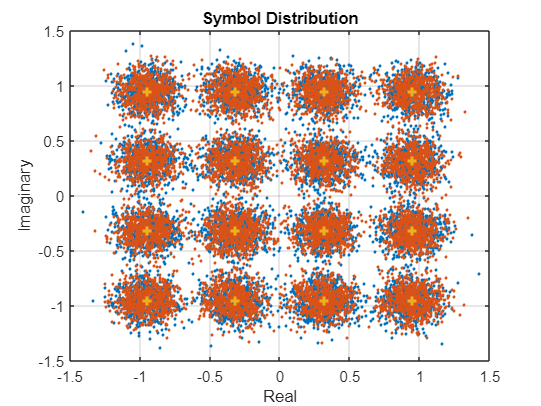

% Using CD compensation on the signals that were not precompensated

for i=1:length(SNRb_dB)
    voltageQAM_CDC(:,:,i) = OverlapSaveCDC(voltageQAM(:,:,i), D, linkLength, CLambda, Rs, 1, SpS, N_FFT, N_CD);
    voltageQAM_CDC_shaped(:,:,i) = OverlapSaveCDC(voltageQAM_shaped_I(:,:,i)+1i*voltageQAM_shaped_Q(:,:,i), D, linkLength, CLambda, Rs, 1, SpS, N_FFT, N_CD);
end

% Downsampling 
voltageQAM_CDC = voltageQAM_CDC(1:SpS:end,:,:);
voltageQAM_CDC_shaped = voltageQAM_CDC_shaped(1:SpS:end,:,:);

voltageQAM_preCD = voltageQAM_preCD(1:SpS:end,:,:);

% Visualising symbol constellations
plot(voltageQAM_CDC_shaped(:,:,end), ".");
hold on
plot(voltageQAM_preCD_shaped_I(:,:,end), voltageQAM_preCD_shaped_Q(:,:,end), ".");
plot(sourceSymbolsQAM(1:100,1), "+", lineWidth=2);
title("Symbol Distribution")
xlabel("Real")
ylabel("Imaginary")
grid on
hold off

### Decision

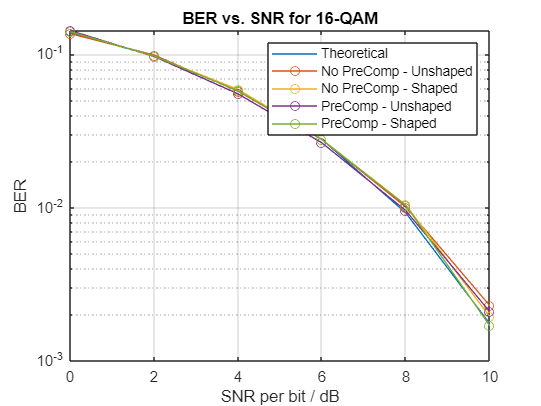

% Decoding and decision

% Without precompensation
decodedInts = qamdemod(voltageQAM_CDC, 16, UnitAveragePower=true);
decodedBits = int2bit(decodedInts, 4);

decodedInts_shaped = qamdemod(voltageQAM_CDC_shaped, 16, UnitAveragePower=true);
decodedBits_shaped = int2bit(decodedInts_shaped, 4);

% With precompensation
decodedInts_preCD = qamdemod(voltageQAM_preCD, 16, UnitAveragePower=true);
decodedBits_preCD = int2bit(decodedInts_preCD, 4);

decodedInts_preCD_shaped = qamdemod(voltageQAM_preCD_shaped_I + 1i*voltageQAM_preCD_shaped_Q, 16, UnitAveragePower=true);
decodedBits_preCD_shaped = int2bit(decodedInts_preCD_shaped, 4);

% Computing BER
BER_QAM = zeros(1, length(SNRb_dB)); BER_QAM_shaped = zeros(1, length(SNRb_dB)); 
BER_QAM_preCD = zeros(1, length(SNRb_dB)); BER_QAM_preCD_shaped = zeros(1, length(SNRb_dB));

for i=1:length(SNRb_dB)
    [~, BER_QAM(:,i)] = biterr(sourceBitsQAM, decodedBits(:,:,i));
    [~, BER_QAM_shaped(:,i)] = biterr(sourceBitsQAM, decodedBits_shaped(:,:,i));
    [~, BER_QAM_preCD(:,i)] = biterr(sourceBitsQAM, decodedBits_preCD(:,:,i));
    [~, BER_QAM_preCD_shaped(:,i)] = biterr(sourceBitsQAM, decodedBits_preCD_shaped(:,:,i));
end

% Plotting BEr vs SNR
semilogy(SNRb_dB, (3/8)*erfc(sqrt(SNRb_Lin*2/5)));
hold on
semilogy(SNRb_dB, BER_QAM, '-o');
semilogy(SNRb_dB, BER_QAM_shaped, '-o');
semilogy(SNRb_dB, BER_QAM_preCD, '-o');
semilogy(SNRb_dB, BER_QAM_preCD_shaped, '-o');
title("BER vs. SNR for 16-QAM");
ylabel("BER");
xlabel("SNR per bit / dB");
legend("Theoretical", "No PreComp - Unshaped", "No PreComp - Shaped", "PreComp - Unshaped", "PreComp - Shaped");
grid on
hold off